## Export Simulink Model to Protected Model with FMU Code Generation Capability

In this section, the following steps illustrate how to enable FMU Code Generation capability of a protected model for FMU export. 

FMU export supports protected model code generation with grt and fmu2cs artifacts. Use [*Simulink.ProtectedModel.getSupportedTargets*](https://www.mathworks.com/help/rtw/ref/simulink.protectedmodel.getsupportedtargets.html?s_tid=doc_ta) to get a list of targets that protected model supports.

The following steps use fmu2cs system target file to generate the protected model. 

This script opens model *DC_core_control.slx, *sets system target file to `fmu2cs.tlc`, creates the project data dictionary, sets the models general configuration and exports the model to a protected model, *DC_core_control_protected.slx*

System target file grt.tlc is also supported for this workflow. Compare to grt.tlc, fmu2cs.tlc supports FMU import block code generation, which allow you to export a model with FMU import blocks to a protected model. If the protected model contains artifacts for both system target file, fmu2cs will take effect when exporting standalone FMU. To learn more about protected model code generation, see [explore protected model capabilities](https://www.mathworks.com/help/simulink/slref/protected-models-for-model-reference.html).

% Open model Controller
base_model = "DC_core_control";
open_system(base_model);

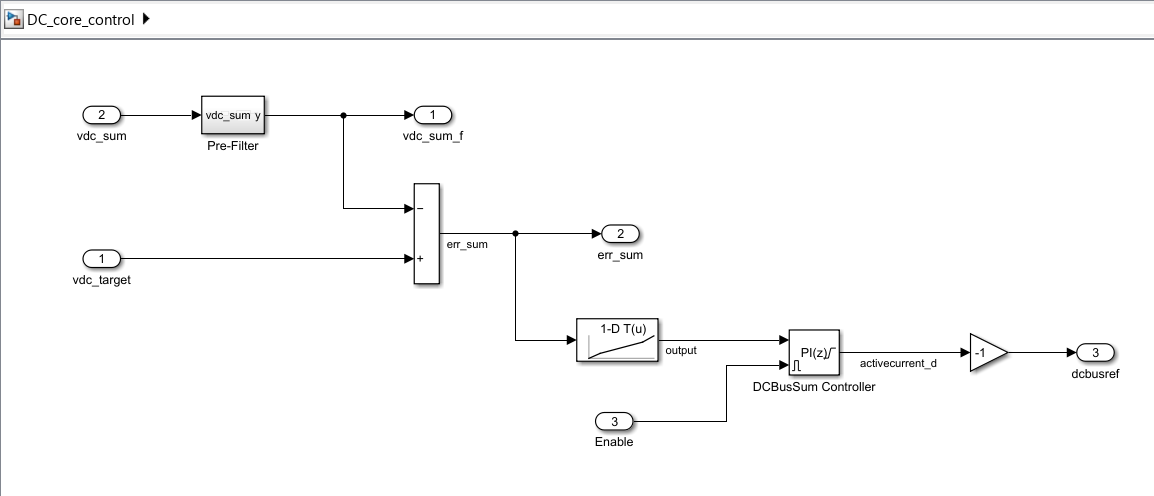

After the model is opened, go to the Save As dialog (Simulation > Save > Save As) and update the **File Name** to DC_core_control_protected. 

% Save model with a different name to avoid warnings when generating the protected model
model = base_model + "_protected";
save_system(base_model, model);

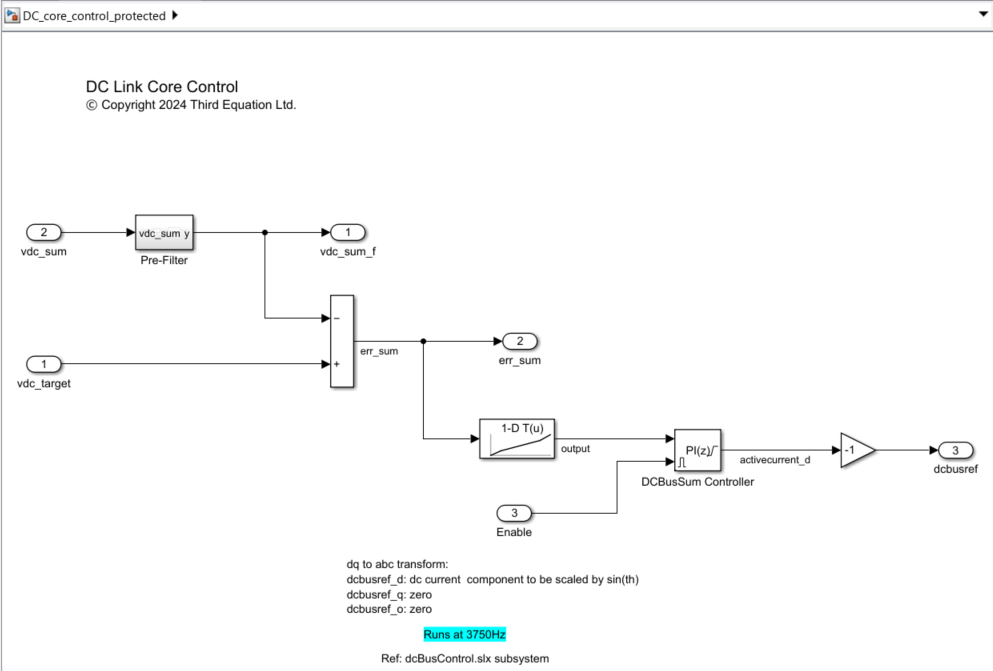

Go to the configuration dialog (Modelling > Model Settings) and update **System target file** to `fmu2cs.tlc` in **Configuration Parameter** > **Code Generation**.

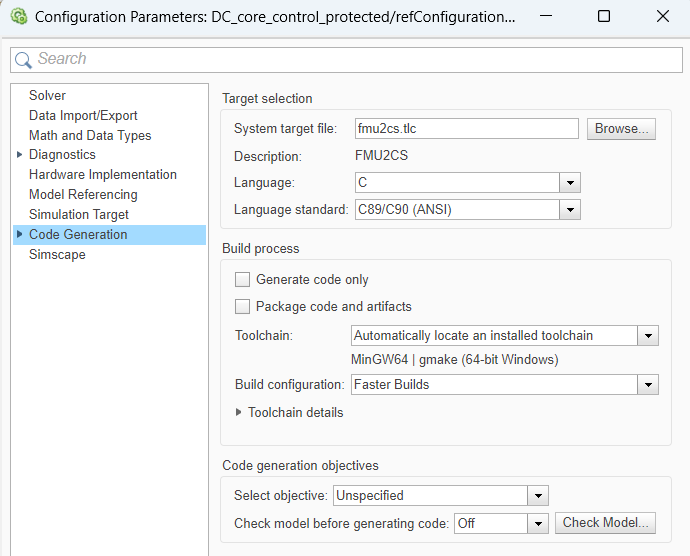

% alternative command-line option to set protected model code generation target to fmu2cs.tlc
% this allows the protected model to be exported as standalone FMU
set_param(model, 'SystemTargetFile', 'fmu2cs.tlc');
set_param(model, 'GRTInterface', 'off');
set_param(model, 'UseToolchainInfoCompliant', 'on');

% to use grt code generation, use command:
% set_param(model, 'SystemTargetFile', 'grt.tlc');

Inconsistent hardware implementation of hardware attributes can result in failure when exporting standalone FMU. To configure these parameters, user can open **Configuration Parameter **> **Hardware Implementation**. Model uses the following setting for code generation:

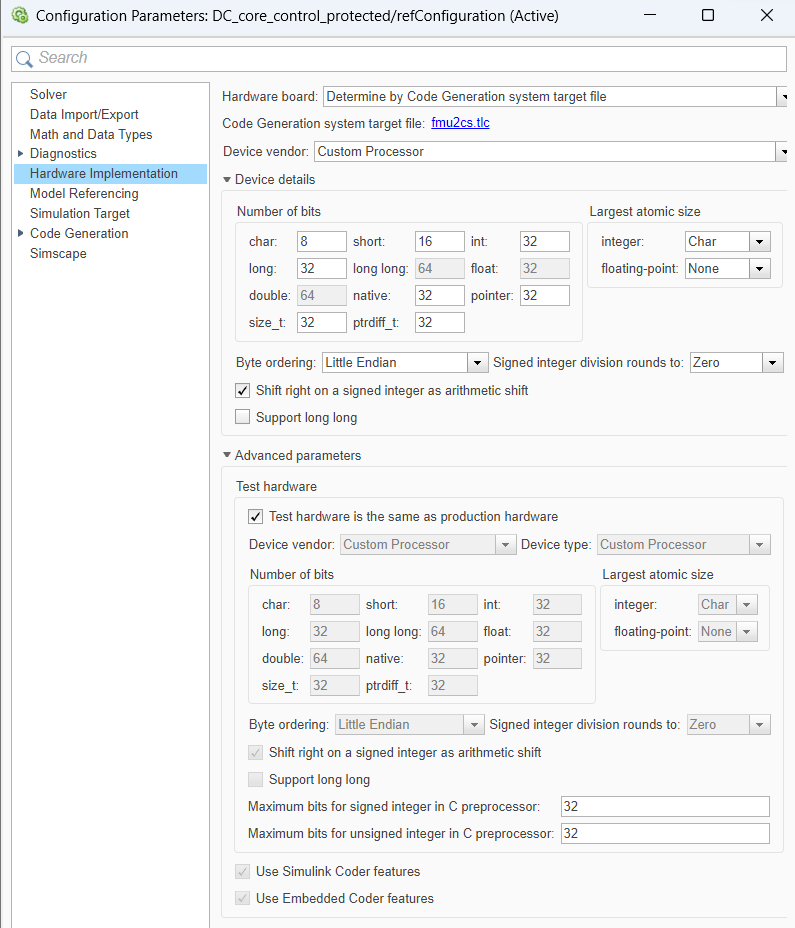

### Include control parameters in the dictionary

Run the core_parameters.m script to add the parameters to the *fmuGenerationDictionary *dictionary.

run("core_parameters.m");

From **Simulation** tab select **Save > Save**

### Generate Protected Model 

From **Simulation** tab select **Save** > **Protected Model**. A dialog box opens where user can select options for creating a protected model.

To enable code generation for standalone FMU export, check **Use Generated Code** and select **Obfuscated source code** in **Content type**. Then select **Protected model (.slp) only** in **Contents**.

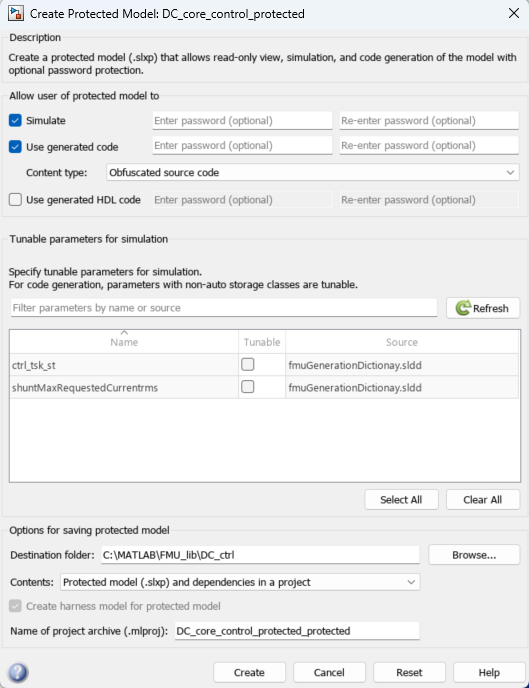

Click on Create. The* DC_core_control_protected.slxp protected model* is created.

% generate protected model
Simulink.ModelReference.protect(model,'Mode','CodeGeneration','ObfuscateCode',true);
% close model after protected model is generated
close_system(model);

*Copyright 2024 Third Edquation Ltd.*